nQubits = 4;
signature_size = 1;
functions = functionsContainer;
message = "10101111111";
codeword = [];
while strlength(message)>= nQubits
    chunk = extractBefore(message, nQubits+1); % Extracts up to index n
    message = extractAfter(message, nQubits);    % Extracts from index n+1
    codeword = [codeword;chunk];
end
if strlength(message) > 0
    last_chunk = "";
    for i = 1:nQubits-strlength(message)
        last_chunk = "0" + last_chunk ;
    end
    last_chunk = message+last_chunk;
    codeword = [codeword;last_chunk];
end


Bob = sender;
Alice = receiver;
seed = 3;
Bob.setSeed(seed);
Alice.setSeed(seed);
Bob.makeCliffordGates();
Alice.makeCliffordGates();
Bob.setPermSet();
Alice.setPermSet();
encrypted_states = Bob.encrypt(codeword);
Alice.decode(encrypted_states);



decoded_message =

  0×0 empty cell array

1 * |1010>
1 * |1111>
1 * |1110>


disp(codeword)

    "1010"
    "1111"
    "1110"



disp(Bob.clifford_gates);

    {62×1 quantum.gate.SimpleGate}



disp(Alice.clifford_gates);

    {62×1 quantum.gate.SimpleGate}



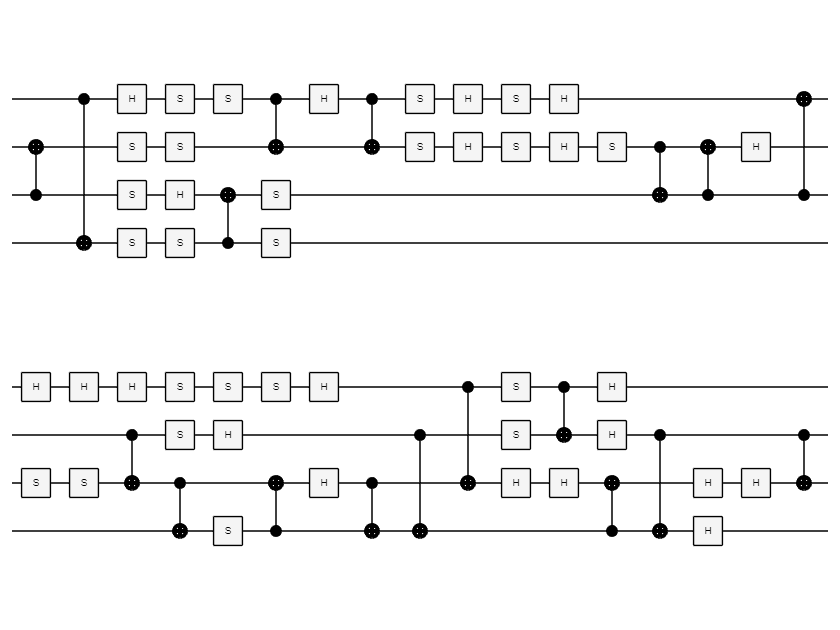

gates = [ Bob.clifford_gates{1}];
C = quantumCircuit(gates);
plot(C);

gates = [ Alice.clifford_gates{1}];
C = quantumCircuit(gates);
plot(C);